# Identification algorithm with filtered DC level

clear;
close all;
clc;
set(0,'defaultfigurecolor',[1 1 1]);
rng('shuffle');

Simulate the alertness level, setting the number of points per hour, sampling approach and the possibility to include or not the first and last data of each window

WL = autoGen(14);

%[dtd,dtn,A] = alertness_gen(1,WL,'random','not');
[dtd,dta] = alertness_sim(2,14,'random','white',40);

% Possibility to use a expecific data--set
% load('data.mat')

Include noise to the data, such as colored or white noise, with a dB intensity determination

% noise_nat = 'colored';
% SNR = 40;
% to = cell2mat(dtd.t);
% 
% if strcmp(noise_nat,'white')
%     e = cell2mat(dtd.y) - awgn(cell2mat(dtd.y),SNR,'measured');
%     yo = cell2mat(dtd.y) + e;
% elseif strcmp(noise_nat,'colored')
%     e = filter(1,[1 -.9],randn(length(cell2mat(dtd.y)),1));
%     v = e*std(cell2mat(dtd.y))*10^(-SNR/20)/std(e);
%     e = v;
%     yo = cell2mat(dtd.y) + e;
% elseif strcmp(noise_nat,'noNoise')
%     yo = cell2mat(dtd.y);
% end
% 
% for w = 1 : length(dtd.y)
%    ind = find((to>=dtd.t{w}(1)).*(to<=dtd.t{w}(end)));
%    dtd.y{w} = yo(ind);
% end

Plot the estimation data and the real simulated alertness level

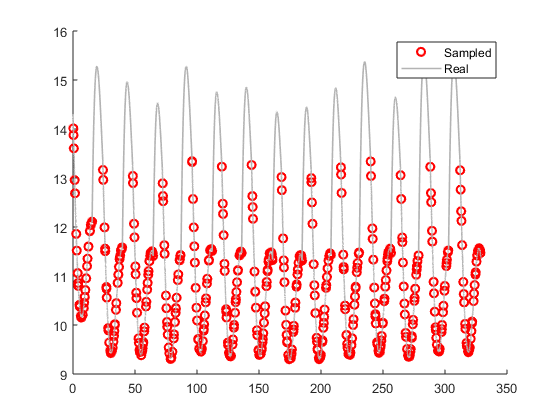

figure(1); 
%plot(A.t,A.A,'-','Color',[.6 .6 .6]); hold on;
scatter(cell2mat(dtd.t),cell2mat(dtd.y),'r','LineWidth',1.6); hold on;
for i = 1 : length(dta.yo)
    plot(dta.td{i},dta.yo{i},'Color',[.7 .7 .7],'LineWidth',1.2); hold on;
    if i ~= length(dta.yo)
        plot(dta.tn{i},dta.yn{i},'Color',[.7 .7 .7],'LineWidth',1.2);
    end
end
%scatter(cell2mat(dtn.t),cell2mat(dtn.y),'bx','LineWidth',1.6);
legend([{'Sampled'},{'Real'}])
hold off;

## Determine the estimation and validation data

est_d = 7;

dte.y = dtd.y(1:est_d); dte.t = dtd.t(1:est_d);
dte.init = dtd.initial(1:est_d); dte.final = dtd.final(1:est_d); 
dte.valid.y = dtd.y(est_d+1:end); dte.valid.t = dtd.t(est_d+1:end);
dte.valid.init = dtd.initial(est_d+1:end); dte.valid.final = dtd.final(est_d+1:end);

%A.valid.Ad = A.Ad(est_d+1:end); A.valid.td = A.td(est_d+1:end);
%A.valid.An = A.An(est_d+1:end); A.valid.tn = A.tn(est_d+1:end);

## Introducing a data filtering approach

First is necessary to look at possible frequency bands of the data. This can be done by a *spa(.)* analysis. But first it is needed to evenlly space the data, and this can be done by resampling aproaches.

To get more reliable results from the data it is interesting to detrend the data before resampling.

% y_o = cell2mat(dte.y); t_o = cell2mat(dte.t);
% 
% avgFs = (numel(t_o)-1)/(t_o(end)-t_o(1));
% 
% fs = 100;
% Fgrid = 25;
% [p,q] = rat(fs/Fgrid);
% 
% %p = 5; q = 5;
% 
% a(1) = (y_o(end)-y_o(1)) / (t_o(end)-t_o(1));
% a(2) = y_o(1);
% 
% xdetrend = y_o - polyval(a,t_o);
% 
% [y_o,t_o] = resample(xdetrend,t_o,fs,p,q,'spline');
% 
% y_o = y_o + polyval(a,t_o);
% 
% figure(2)
% plot(cell2mat(A.td),cell2mat(A.Ad),'-','Color',[.6 .6 .6]); hold on;
% plot(t_o,y_o,'r--');
% scatter(cell2mat(dte.t),cell2mat(dte.y),'xb');
% w = linspace(.01,50,10000);
% Ts = A.td{1}(2) - A.td{1}(1);
% rData = iddata(cell2mat(A.Ad),[],Ts);
% rG = spa(rData,[],w);
% rG = chgFreqUnit(rG,'Hz');
% 
% dts.y = cell(length(dte.y),1);
% dts.t = cell(length(dte.t),1);
% for k = 1 : length(dte.y)
%     ind = find((t_o>=dte.t{k}(1)).*(t_o<=dte.t{k}(end)));
%     dts.t{k} = t_o(ind);
%     dts.y{k} = y_o(ind);
% end
% 
% Ts = dts.t{1}(2) - dts.t{1}(1);
% sData = iddata(cell2mat(dts.y),[],Ts);
% sG = spa(sData,[],w);
% sG = chgFreqUnit(sG,'Hz');
% 
% figure(3);
% aux = reshape(rG.SpectrumData,length(rG.Frequency),1);
% plot(rG.Frequency,aux,'Color',[.7 .7 .7],'LineWidth',1.2); hold on;
% aux = reshape(sG.SpectrumData,length(sG.Frequency),1);
% plot(sG.Frequency,aux,'r--','LineWidth',1.2);
% set(gca, 'XScale', 'log');
% dte.y = dts.y; dte.t = dts.t;

## Select the model structure

It is possible to select the filtereing structure by a *trivial* form ***i.e.*** setting the filtering poles $\omega_c = \frac{\pi}{2}$ or by using a derivative-free *barycenter *approach for searching the best choice 

struc = struc_select('trivial',dte);

## Estimate the models parameters

parameters = est_regr(dte,struc,'16');

## Simulate the alertness level

time.init = [dte.valid.t{1}(1), dte.valid.init(2:end)];
time.final = dte.valid.final;
initial = dte.valid.y{1}(1);

dts = sim_system(parameters,time,initial);

## Figures Generation

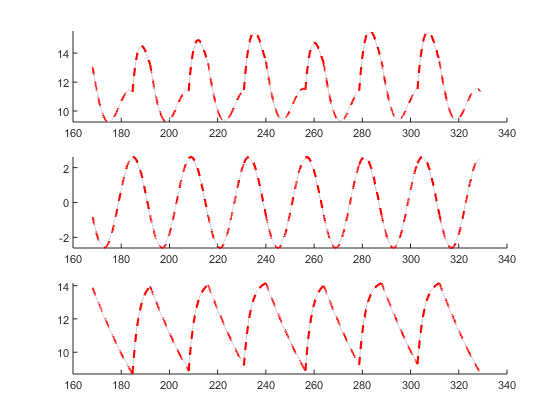

figure(4); 
% subplot(3,1,1); hold on;
% plot(A.t,A.A,'-','Color',[.8 .8 .8]);
% subplot(3,1,2); hold on;
% plot(A.t,parameters.real.M*cos(parameters.real.omega*A.t + ...
%                                             parameters.real.cphase),...
%                                                    '-','Color',[.8 .8 .8]);
% subplot(3,1,3); hold on;
% plot(A.t,A.A - parameters.real.M*cos(parameters.real.omega*A.t + ...
%                                                 parameters.real.cphase),...
%                                                    '-','Color',[.8 .8 .8]);
for i = 1 : length(dts.y)
    i_s = i + est_d;
    subplot(3,1,1); hold on;
    plot(dta.td{i_s},dta.yo{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.yd{i},'r--','LineWidth',1.6);
    subplot(3,1,2); hold on;
    plot(dta.td{i_s},dta.yo{i_s} - dta.dhom{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.yd{i} - dts.dhom{i},'r--','LineWidth',1.6);
    subplot(3,1,3); hold on;
    plot(dta.td{i_s},dta.dhom{i_s},'Color',[.8 .8 .8]); hold on;
    plot(dts.td{i},dts.dhom{i},'r--','LineWidth',1.6);
   
    if i ~= length(dts.y)
        subplot(3,1,1); hold on;
        plot(dta.tn{i_s},dta.yn{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.yn{i},'r--','LineWidth',1.6);
        subplot(3,1,2); hold on;
        plot(dta.tn{i_s},dta.yn{i_s} - dta.nhom{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.yn{i} - dts.nhom{i},'r--','LineWidth',1.6);
        subplot(3,1,3); hold on;
        plot(dta.tn{i_s},dta.nhom{i_s},'Color',[.8 .8 .8]); hold on;
        plot(dts.tn{i},dts.nhom{i},'r--','LineWidth',1.6);    
    end
end